# Comparison of Estimation Performance for Angle and Frequency Estimation - individual ESPRIT and joint diagonalization

## Parameters

M = 3;                  % no. of antennas
N = 20;                 % no. of samples
Delta = 1/2;            % spacing b/w antennas (in terms of wavelength)
theta = [-20, 30];      % directions of sources (in degrees) (-90 to 90)
f = [0.1, 0.12];        % normalized frequency (b/w 0 and 1)
d = length(theta);      % no. of sources
m = d * 2;              % time smoothing factor, using m = 2d
SNR_range = 0:4:20;     % range of SNRs (in dB)
num_trials = 1000;      % no. of trials

## Array initialization for storing results

theta_esprit_mean = zeros(length(SNR_range), d);
theta_esprit_std = zeros(length(SNR_range), d);
f_espritfreq_mean = zeros(length(SNR_range), d);
f_espritfreq_std = zeros(length(SNR_range), d);
theta_joint_mean = zeros(length(SNR_range), d);
theta_joint_std = zeros(length(SNR_range), d);
f_joint_mean = zeros(length(SNR_range), d);
f_joint_std = zeros(length(SNR_range), d);

## Simulation over SNR Range

for snr_idx = 1:length(SNR_range)
    SNR = SNR_range(snr_idx);

    % arrays to store estimates for current SNR
    theta_esprit_estimates = zeros(num_trials, d);
    f_espritfreq_estimates = zeros(num_trials, d);
    theta_joint_estimates = zeros(num_trials, d);
    f_joint_estimates = zeros(num_trials, d);

    % trials
    for trial = 1:num_trials
        % generating data with current SNR
        [X, ~, ~] = gendata(M, N, Delta, theta, f, SNR);

        % applying algorithms
        theta_esprit = esprit(X, d);
        f_espritfreq = espritfreq(X, d);
        [theta_joint, f_joint] = joint(X, d, m);

        % storing results (with sorting)
        [~, sort_idx_theta] = sort(abs(theta_esprit - theta(1)));
        theta_esprit_estimates(trial, :) = theta_esprit(sort_idx_theta)';

        [~, sort_idx_f] = sort(abs(f_espritfreq - f(1)));
        f_espritfreq_estimates(trial, :) = f_espritfreq(sort_idx_f)';

        [~, sort_idx_theta_joint] = sort(abs(theta_joint - theta(1)));
        theta_joint_estimates(trial, :) = theta_joint(sort_idx_theta_joint)';

        [~, sort_idx_f_joint] = sort(abs(f_joint - f(1)));
        f_joint_estimates(trial, :) = f_espritfreq(sort_idx_f_joint)';
    end

    % calculating mean and standard deviation for current SNR
    theta_esprit_mean(snr_idx, :) = mean(theta_esprit_estimates);
    theta_esprit_std(snr_idx, :) = std(theta_esprit_estimates);

    f_espritfreq_mean(snr_idx, :) = mean(f_espritfreq_estimates);
    f_espritfreq_std(snr_idx, :) = std(f_espritfreq_estimates);

    theta_joint_mean(snr_idx, :) = mean(theta_joint_estimates);
    theta_joint_std(snr_idx, :) = std(theta_joint_estimates);

    f_joint_mean(snr_idx, :) = mean(f_joint_estimates);
    f_joint_std(snr_idx, :) = std(f_joint_estimates);

    % displaying process
    fprintf('Completed SNR = %d dB\n', SNR);
end

Completed SNR = 0 dB
Completed SNR = 4 dB
Completed SNR = 8 dB
Completed SNR = 12 dB
Completed SNR = 16 dB
Completed SNR = 20 dB


## Result Plotting

### Angle Estimation Comparison

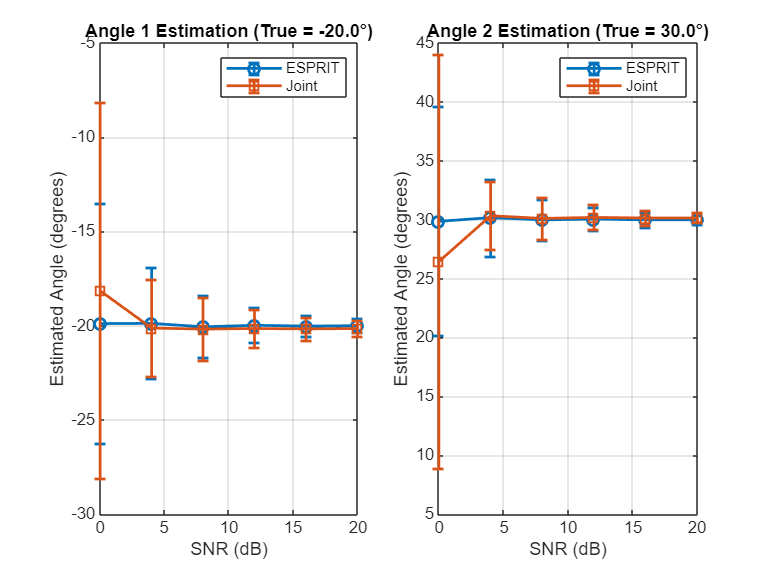

figure(1);

% first angle
subplot(1,2,1);
errorbar(SNR_range, theta_esprit_mean(:,1), theta_esprit_std(:,1), 'o-', 'LineWidth', 1.5);
hold on;
errorbar(SNR_range, theta_joint_mean(:,1), theta_joint_std(:,1), 's-', 'LineWidth', 1.5);
hold off;
grid on;
title(sprintf('Angle 1 Estimation (True = %.1f°)', theta(1)));
xlabel('SNR (dB)');
ylabel('Estimated Angle (degrees)');
legend('ESPRIT', 'Joint');

% second angle
subplot(1,2,2);
errorbar(SNR_range, theta_esprit_mean(:,2), theta_esprit_std(:,2), 'o-', 'LineWidth', 1.5);
hold on;
errorbar(SNR_range, theta_joint_mean(:,2), theta_joint_std(:,2), 's-', 'LineWidth', 1.5);
hold off;
grid on;
title(sprintf('Angle 2 Estimation (True = %.1f°)', theta(2)));
xlabel('SNR (dB)');
ylabel('Estimated Angle (degrees)');
legend('ESPRIT', 'Joint');

### Frequency Estimation Comparison

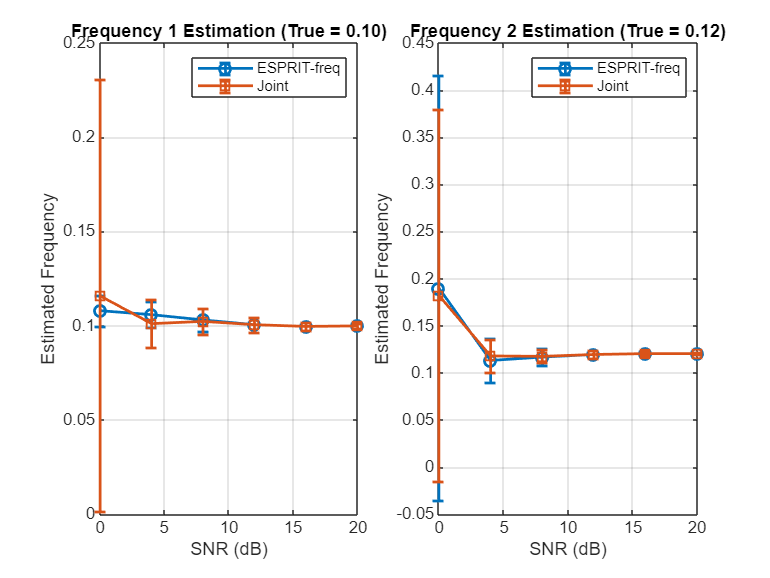

figure(2);

% first frequency
subplot(1,2,1);
errorbar(SNR_range, f_espritfreq_mean(:,1), f_espritfreq_std(:,1), 'o-', 'LineWidth', 1.5);
hold on;
errorbar(SNR_range, f_joint_mean(:,1), f_joint_std(:,1), 's-', 'LineWidth', 1.5);
hold off;
grid on;
title(sprintf('Frequency 1 Estimation (True = %.2f)', f(1)));
xlabel('SNR (dB)');
ylabel('Estimated Frequency');
legend('ESPRIT-freq', 'Joint');

% second frequency
subplot(1,2,2);
errorbar(SNR_range, f_espritfreq_mean(:,2), f_espritfreq_std(:,2), 'o-', 'LineWidth', 1.5);
hold on;
errorbar(SNR_range, f_joint_mean(:,2), f_joint_std(:,2), 's-', 'LineWidth', 1.5);
hold off;
grid on;
title(sprintf('Frequency 2 Estimation (True = %.2f)', f(2)));
xlabel('SNR (dB)');
ylabel('Estimated Frequency');
legend('ESPRIT-freq', 'Joint');